# InterpolatingSpline

An interpolating spline uses local b-splines to interpolate across points. The (K-1)th derivative of a K order spline is piecewise continuous.

Let's start by defining a  function,

L = 10;
f = @(x) sin(2*pi*x/L);

create a grid of observation points,

N = 10;
x = linspace(0,2*L,N)';

and then sampling the function at the observation points

y = f(x);

Let's create a dense grid in x just to better visualize the true function, and the sample points.

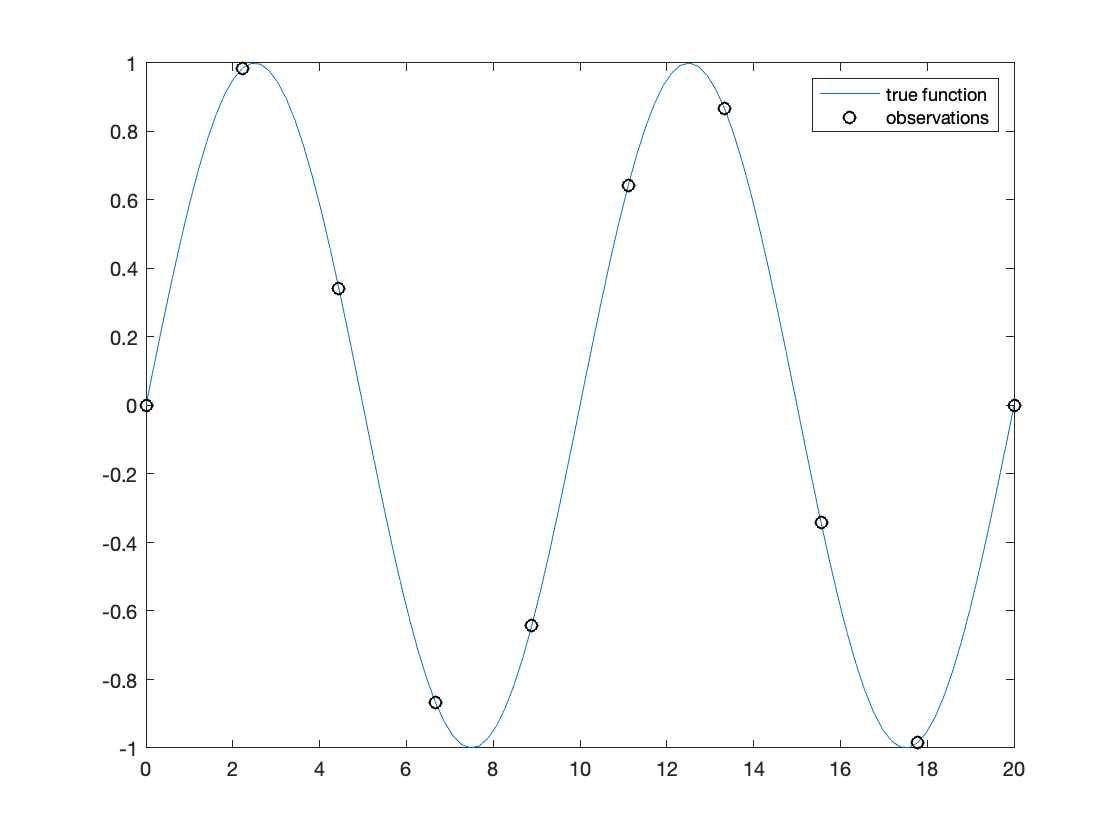

x_dense = linspace(0,2*L,10*N)';

figure
plot(x_dense,f(x_dense)), hold on
scatter(x,y,'k')
legend('true function', 'observations')

Finally, let's use an interpolating spline,

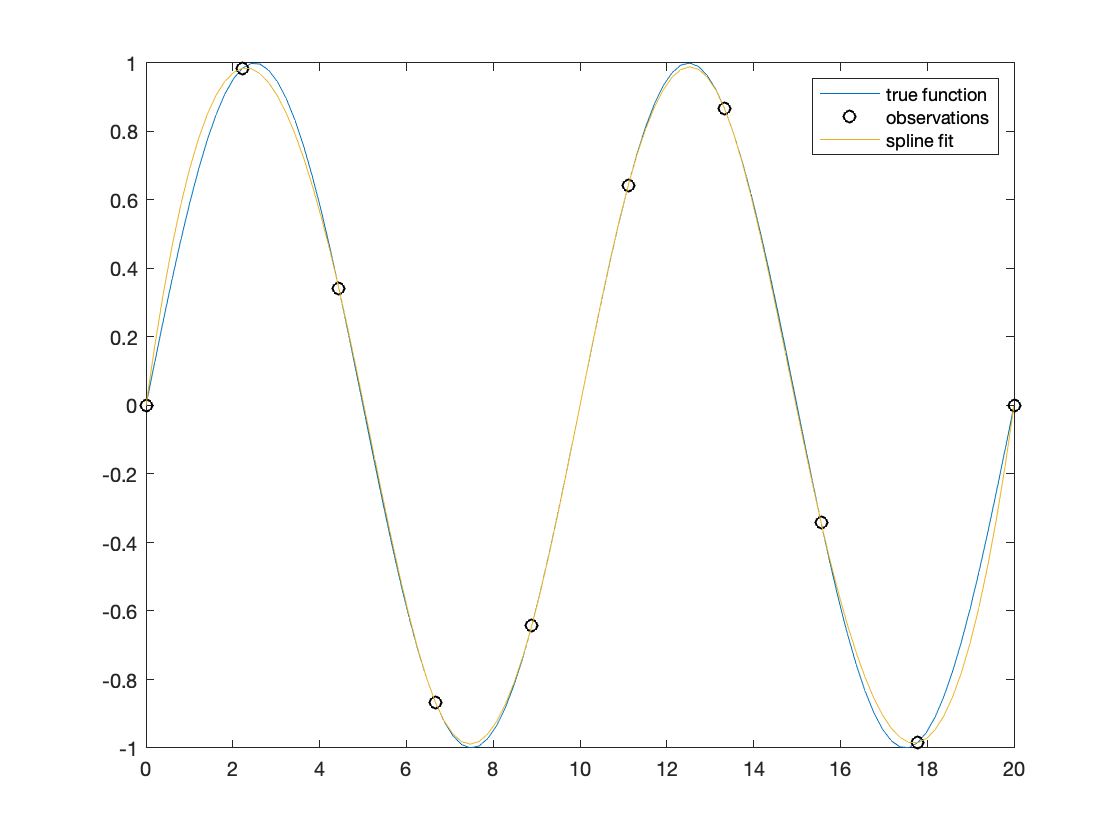

spline = InterpolatingSpline(x,y);

figure
plot(x_dense,f(x_dense)), hold on
scatter(x,y,'k')
plot(x_dense,spline(x_dense))
legend('true function', 'observations', 'spline fit')

This spline fit is identical to Matlab's built in griddedInterpolant with the 'spline' option,

ginterp = griddedInterpolant(x,y,'spline');

residual = ginterp(x_dense)-spline(x_dense);
relative_error = max(abs(residual))/max(abs(y))

relative_error = 4.5094e-16

However, unlike Matlab's implementation, this class lets you specify the order of the spline to something other than cubic (K=4). For example, we can do a K=2 fit (which is just linear interpolation), but also a (K=5) fit.

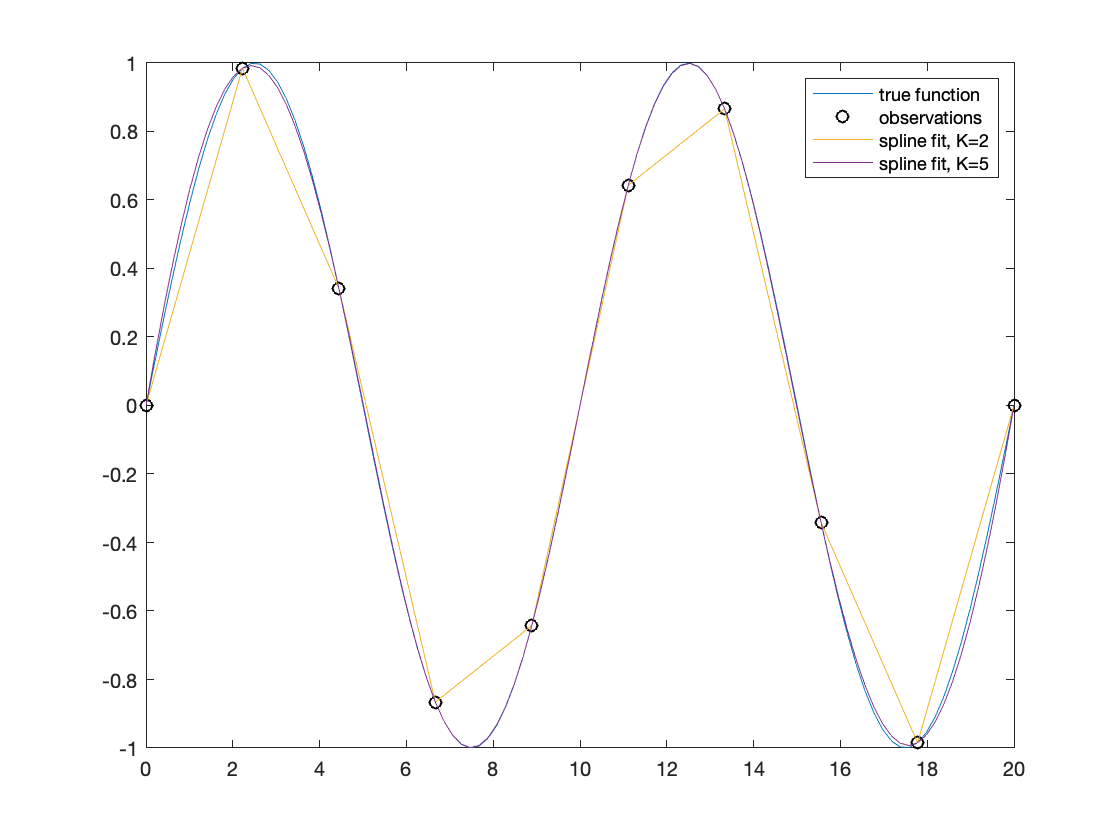

spline_2 = InterpolatingSpline(x,y,'K',2);
spline_5 = InterpolatingSpline(x,y,'K',5);

figure
plot(x_dense,f(x_dense)), hold on
scatter(x,y,'k')
plot(x_dense,spline_2(x_dense))
plot(x_dense,spline_5(x_dense))
legend('true function', 'observations', 'spline fit, K=2', 'spline fit, K=5')